# Get Started with Solver-Based Optimize Live Editor Task

This example script helps you to use the solver-based **Optimize** Live Editor task for optimization or equation solving. Modify the script for your own problem.

The script solves a nonlinear optimization problem with nonlinear constraints.

## Include Parameters or Data

Typically, you have data or values to pass to the solver. Place those values in the input section (where you see `x0`) and run the section by choosing **Section > Run Section** or pressing `Control+Enter`.

Set the initial point `x0` and scale `a` for the optimization.

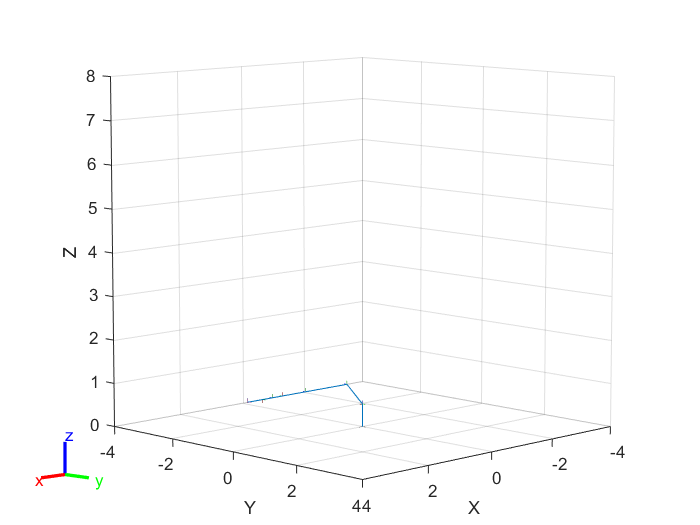

x0 = [2;1];
a = 100;

lb = [-3,-3];
ub = [3,3];

KSetUp;

KPfadgenerator;

**Place the **`x0`** value and any other problem data into the workspace** by running this section before proceeding.

## Optimize Live Editor Task

Usually, you place the Optimize Live Editor task into the script by selecting **Task > Optimize** in the **Live Editor** tab, or by selecting **Task > Optimize** in the **Insert** tab. Then you are presented with the following choice (this is only a picture, not the real task):

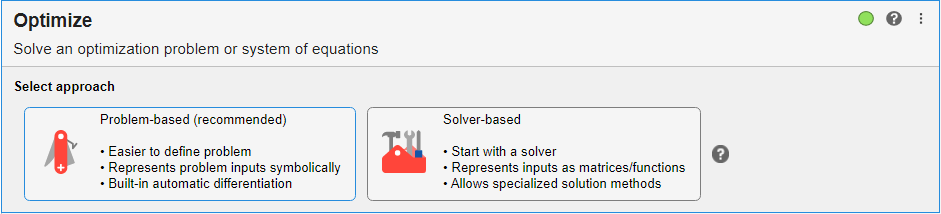

To get the solver-based task, click **Solver-based**.

The following solver-based task has objective and nonlinear constraint functions included. To change these functions, edit the function listings below the task.

To change the constraints, select appropriate constraint types and enter values in the input boxes. You might need to enter values in the section containing `x0` above, and run the section to put values in the workspace.

Run the task by clicking the striped bar to the left, or by choosing **Run** or **Section > Run Section**, or by pressing `Control+Enter`.

disp('Please select: Lower bounds constraints')

## Results

`Optimize` saves the solution to the workspace variable `solution`, and saves the objective function value at the solution to the workspace variable `objectiveValue`. You can see and modify these variable names at the top of the `Optimize` task.

View these variables.

solution
objectiveValue

View the nonlinear constraint function values at the solution.

[ccons,ceqcons] = constraintFcn(solution)

## Helper Functions — Local Functions

The followings code creates the objective function. Modify this code for your problem.

function f = objectiveFcn(x,a)
    timeintervals = x(1:size(x,1)-1,1);
    base_points = x(:,2:size(x,2));
    objective = sum(timeintervals); 
    for i=1:size(base_points,2)
        [t,td,tdd,tddd,time,place] = spline(base_points(:,i),timeintervals,false);
        %0.0001
        objective = objective + 0.0001 * trapz((tdd.^2)); %TODO 
    end
end

The following code creates the constraint function. Modify this code for your problem.

function [c,ceq] = constraintFcn(x)
KSetUp;
KPfadgenerator;
init_ax_values = [ones(size(minJerkPath,1),1) minJerkPath];
init_ax_values(:,1) = 0.3; %Anfängliche Beschleunigung = 0,3m/s???

regression = load("regressionKat4.mat");
simulation_data = readtable('simulationData.txt');

Test = constraintFcnValidation(x,init_ax_values,regression,simulation_data)
end

*Copyright 2020 The MathWorks, Inc.*